# **Variable Frequency Drive  for Induction Motor**

clear all                               % Clears command history
close all                               % Closes  all windows
clc                                     % Clears command window

V=230;                                  %supply voltage
V_p=230/sqrt(3);                        %per phase voltage
n=3;                                    %no. of phases
p=4;                                    %no. of poles
R1=0.6;                                 %stator resistance (ohm)
R2=0.4;                                 %rotor resistance wrt stator (ohm)
X1=0.680;                               %stator reactance (ohm)
X2=0.672;                               %rotor reactance wrt stator (ohm)
f=linspace(10,50,10);                   %frequency

Equivalent circuit of Induction motor

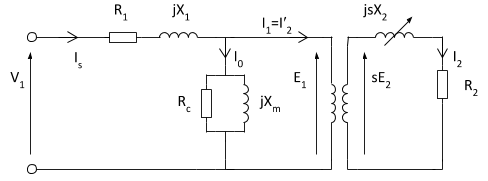

Here

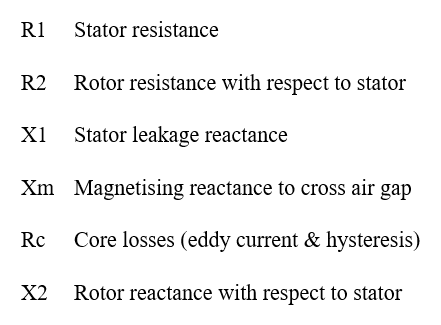

The torque developed by induction motor is given by- 


$$T=\frac{3}{\omega_{ms} }{\left(\frac{V^2 R_2 ∕s}{{{\left(R_1 +\frac{R_2 }{s}\right)}}^2 +{{\left(X_1 +X_2 \right)}}^2 }\right)}$$


Where the synchronous speed in rad/sec, V is the voltage applied to the stator,  and  are rotor resistance and reactance with respect to stator respectively, and  are stator resistance and reactance respectively.

Slip is defined by


$$s=\frac{\omega_{ms} -\omega_m }{\omega_{ms} }$$


Where  &  are synchronous and rotor speed respectively. Further 

 
$$\omega_{ms} =\frac{4\pi f}{P}$$


Where f and P are frequency and number of poles respectively.

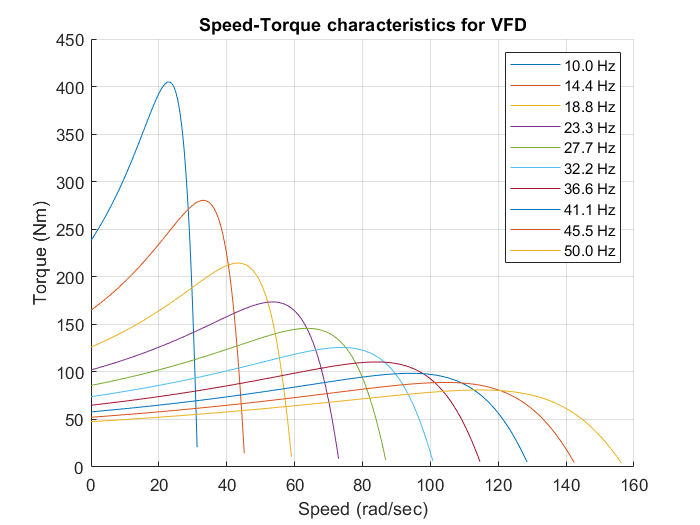

for i=1:10
    w_ms=(4.*pi.*f(i))./p;              %synchronous speed (rps)
    for j=1:200
        s(j)=j/200;                     %slip
        w_m(j)=(1-s(j))*w_ms;           %rotor speed
        T(j)=3./w_ms.*(((V_p.^2.*R2)./s(j))./((R1+(R2./s(j))).^2 +(X1+X2).^2));     %torque developed in rotor
    end
    hold on 
    plot (w_m,T)
    grid on  
end
    xlabel('Speed (rad/sec)')
    ylabel('Torque (Nm)')
    title('Speed-Torque characteristics for VFD')
    legend('10.0 Hz','14.4 Hz','18.8 Hz','23.3 Hz','27.7 Hz','32.2 Hz','36.6 Hz','41.1 Hz','45.5 Hz','50.0 Hz')